# 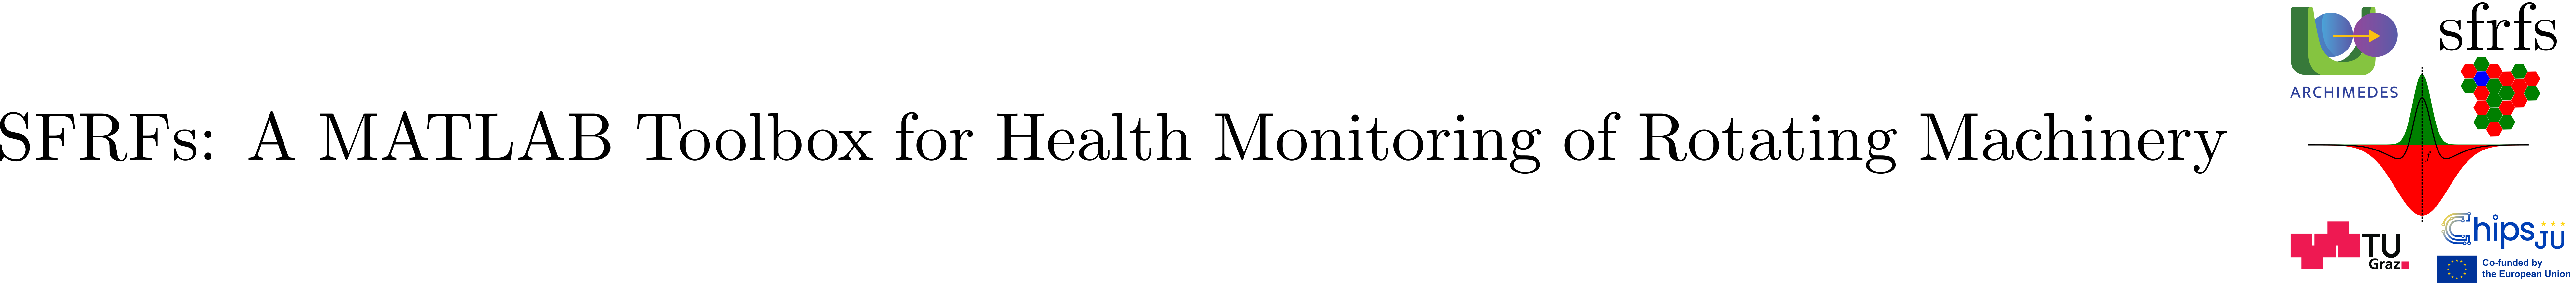

# ParametersSnapshot

## Summary

Class representing snapshot metadata for signal processing, encapsulating independent parameters related to sampling and snapshot timing.

Key properties:

- `samplingFrequency`: Sampling frequency in Hz.

- `duration`: Duration (seconds) of the snapshot window.

- `stride`: Time interval in seconds between consecutive snapshot start times.

Key methods:

- Constructor initializes the properties with validation and logs a formatted description.

- `getTotalSamples`: Returns the total number of samples in a snapshot, caching the result for efficiency.

- `toString`: Provides a formatted string summarizing the snapshot parameters.

- `getFrequencyDomain`: Computes the FFT frequency axis vector corresponding to the snapshot length and sampling frequency.

This class encapsulates fundamental timing and sampling parameters essential for accurate spectral and time-domain signal processing.

## Description

***Snapshots*** are defined as periodic signal recordings. Each recording corresponds to a finite **time window** of fixed, predefined length. The number of **samples** (instantaneous measurements) in a snapshot depends on the **sampling frequency**. The **snapshot period** (or stride) refers to the time in seconds between two consecutive snapshots. 

## Example

We illustrate the definition of snapshots using the [**XJTU-SY**](https://github.com/WangBiaoXJTU/xjtu-sy-bearing-datasets) rolling bearing run-to-failure dataset. Figure 1 (see Reference [1]) depicts the snapshot parameters applicable for the horizontal and vertical accelerations monitoring bearing degradation.

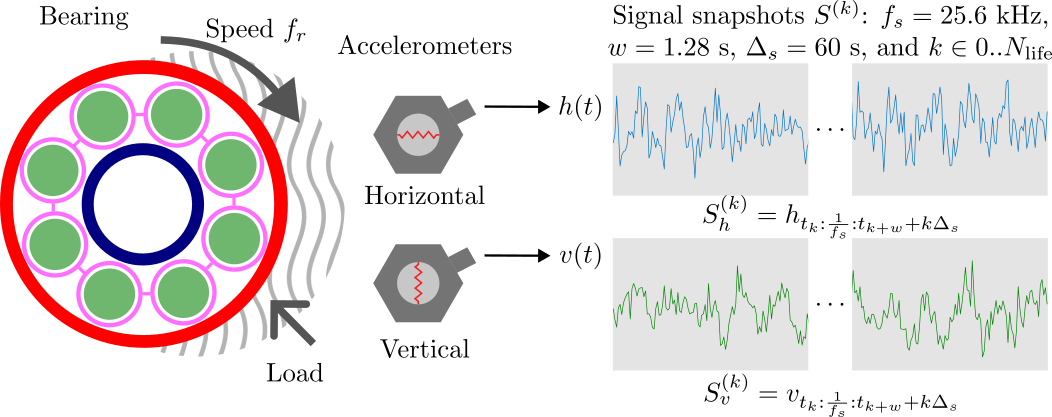

**Figure 1**. Vibration signal snapshots for a rolling bearing. Vibrations are detected using accelerometers for the horizontal and vertical directions. Each snapshot has a *duration*  $$w = 1.28$$ s, the stride $$\Delta_s = 60$$ s (1 snapshot per minute). In this example, taken from **XJTU-SY** rolling bearing run-to-failure dataset (see Reference [2]), the sampling frequency $$f_s = 25.6$$ kHz. 

### Object creation

The following code shows how to create an instance of the object. Properties are specified as named parameters to aid interpretability.

% Creates the descriptor for signal snapshots of XJTU-SY dataset
params = ParametersSnapshot(...
        'samplingFrequency', 25600, ...
        'duration', 1.28, ...
        'stride', 60);

% the class implements toString method
params

params =   ParametersSnapshot with properties:

    samplingFrequency: 25600
             duration: 1.2800
               stride: 60


### Number of samples

The number of samples can be queried with the method `getTotalSamples.`

disp(params.getTotalSamples())

       32768



### `String representation`

The class is a value object and provides a string rendering via toString method.

disp(params.toString)

[ParametersSnapshot: fs=25600.00 Hz, duration=1.280 s, stride=60.000 s]


### Frequency axis

The method `getFrequencyDomain`, obtains the frequency domain axis segment corresponding to the the FFT of the snapshot.

freq_axis = params.getFrequencyDomain();
fprintf('Frequency axis: %d points, from %.2f Hz to %.2f kHz\n', ...
    numel(freq_axis), freq_axis(1), freq_axis(end)/1.e3);

Frequency axis: 32768 points, from 0.00 Hz to 25.60 kHz


## API documentation

### MATLAB help

help ParametersSnapshot

  ParametersSnapshot: Parameter object describing snapshot metadata
  Independent parameters for sampling and snapshot timing.
 
  Properties:
    samplingFrequency - Sampling frequency (Hz)
    duration          - Snapshot window duration (seconds)
    stride            - Time interval between consecutive snapshot 
                        start times (seconds)
 
  Example:
    params = ParametersSnapshot(...
        'samplingFrequency', 25600, ...
        'duration', 1.28, ...
        'stride', 60);
    disp(params.toString())

    Documentation for ParametersSnapshot
       doc ParametersSnapshot




### MATLAB documentation

doc ParametersSnapshot

Opens the full class documentation in the MATLAB Help Browser, including formatted examples, links to related functions, and extended descriptions.

## Source code

Snapshot metadata is implemented in the class [ParametersSnapshot](matlab:open('../../ParametersSnapshot.m')).

## Test

Unit testing for the class is implemented in [TestParametersSnapshot](matlab:open('../../../tests/TestParametersSnapshot.m')). Test the class as follows:

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/TestParametersSnapshot');

Running TestParametersSnapshot
.....
Done TestParametersSnapshot
__________



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestParametersSnapshot/testCreationAndProperties                                 | Passed
TestParametersSnapshot/testGetTotalSamplesComputation                            | Passed
TestParametersSnapshot/testNegativeOrZeroValuesThrow                             | Passed
TestParametersSnapshot/testGetFrequencyDomain                                    | Passed
TestParametersSnapshot/testGetTimeAxisFromProperties                             | Passed



## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).

- [2] Biao Wang, Yaguo Lei, Naipeng Li, Ningbo Li, “A Hybrid Prognostics Approach for Estimating Remaining Useful Life of Rolling Element Bearings”, IEEE Transactions on Reliability, pp. 1-12, 2018. [DOI: 10.1109/TR.2018.2882682](https://doi.org/10.1109/TR.2018.2882682).